% Tensor Component Analysis (TCA): via Tucker Decomposition (TD)
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLA'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

pre_data = beta_signal(:, pre_idx,:); % ch x time x trial
post_data = beta_signal(:, post_idx,:); % ch x time x trial

% Define the range of components to test
num_components = 1:32;  % Test 1 to 32 components, Tucker Decomposition max number of components equals the smallest dimension of the tensor
reconstruction_errors_pre = zeros(size(num_components));
explained_variance_pre = zeros(size(num_components));
reconstruction_errors_post = zeros(size(num_components));
explained_variance_post = zeros(size(num_components));

if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end

% Convert data to tensor object
pre_tensor = tensor(pre_data);
post_tensor = tensor(post_data);

% Replace your existing parfor loop with this code for Tucker Decomposition
parfor idx = 1:length(num_components)
    k = num_components(idx);
   
    % Tucker decomposition for pre-stimulus data
    % Using the same rank k for all modes
    tucker_ranks = [k, k, k];
    tucker_pre = tucker_als(pre_tensor, tucker_ranks, 'tol', 1e-4, 'maxiters', 50);
    
    % Reconstruct the tensor from the Tucker model
    reconstructed_pre = full(tucker_pre);
    
    % Calculate reconstruction error and explained variance
    error_pre = norm(pre_tensor(:) - reconstructed_pre(:)) / norm(pre_tensor(:));
    reconstruction_errors_pre(idx) = error_pre;
    explained_variance_pre(idx) = 1 - error_pre^2;
    
    % Tucker decomposition for post-stimulus data
    tucker_post = tucker_als(post_tensor, tucker_ranks, 'tol', 1e-4, 'maxiters', 50);
    
    % Reconstruct the tensor from the Tucker model
    reconstructed_post = full(tucker_post);
    
    % Calculate reconstruction error and explained variance
    error_post = norm(post_tensor(:) - reconstructed_post(:)) / norm(post_tensor(:));
    reconstruction_errors_post(idx) = error_post;
    explained_variance_post(idx) = 1 - error_post^2;
end


Tucker Alternating Least-Squares:
 Iter  1: fit = 1.387262e-02 fitdelta = 1.4e-02
 Iter  2: fit = 3.296315e-02 fitdelta = 1.9e-02
 Iter  3: fit = 3.750214e-02 fitdelta = 4.5e-03
 Iter  4: fit = 3.949451e-02 fitdelta = 2.0e-03
 Iter  5: fit = 4.046832e-02 fitdelta = 9.7e-04
 Iter  6: fit = 4.094407e-02 fitdelta = 4.8e-04
 Iter  7: fit = 4.117777e-02 fitdelta = 2.3e-04
 Iter  8: fit = 4.129624e-02 fitdelta = 1.2e-04
 Iter  9: fit = 4.135908e-02 fitdelta = 6.3e-05

Tucker Alternating Least-Squares:
 Iter  1: fit = 1.734598e-02 fitdelta = 1.7e-02
 Iter  2: fit = 2.716356e-02 fitdelta = 9.8e-03
 Iter  3: fit = 2.956941e-02 fitdelta = 2.4e-03
 Iter  4: fit = 3.083510e-02 fitdelta = 1.3e-03
 Iter  5: fit = 3.144011e-02 fitdelta = 6.1e-04
 Iter  6: fit = 3.170678e-02 fitdelta = 2.7e-04
 Iter  7: fit = 3.183196e-02 fitdelta = 1.3e-04
 Iter  8: fit = 3.190369e-02 fitdelta = 7.2e-05

Tucker Alternating Least-Squares:
 Iter  1: fit = 9.540303e-02 fitdelta = 9.5e-02
 Iter  2: fit = 1.502736e-01 fi

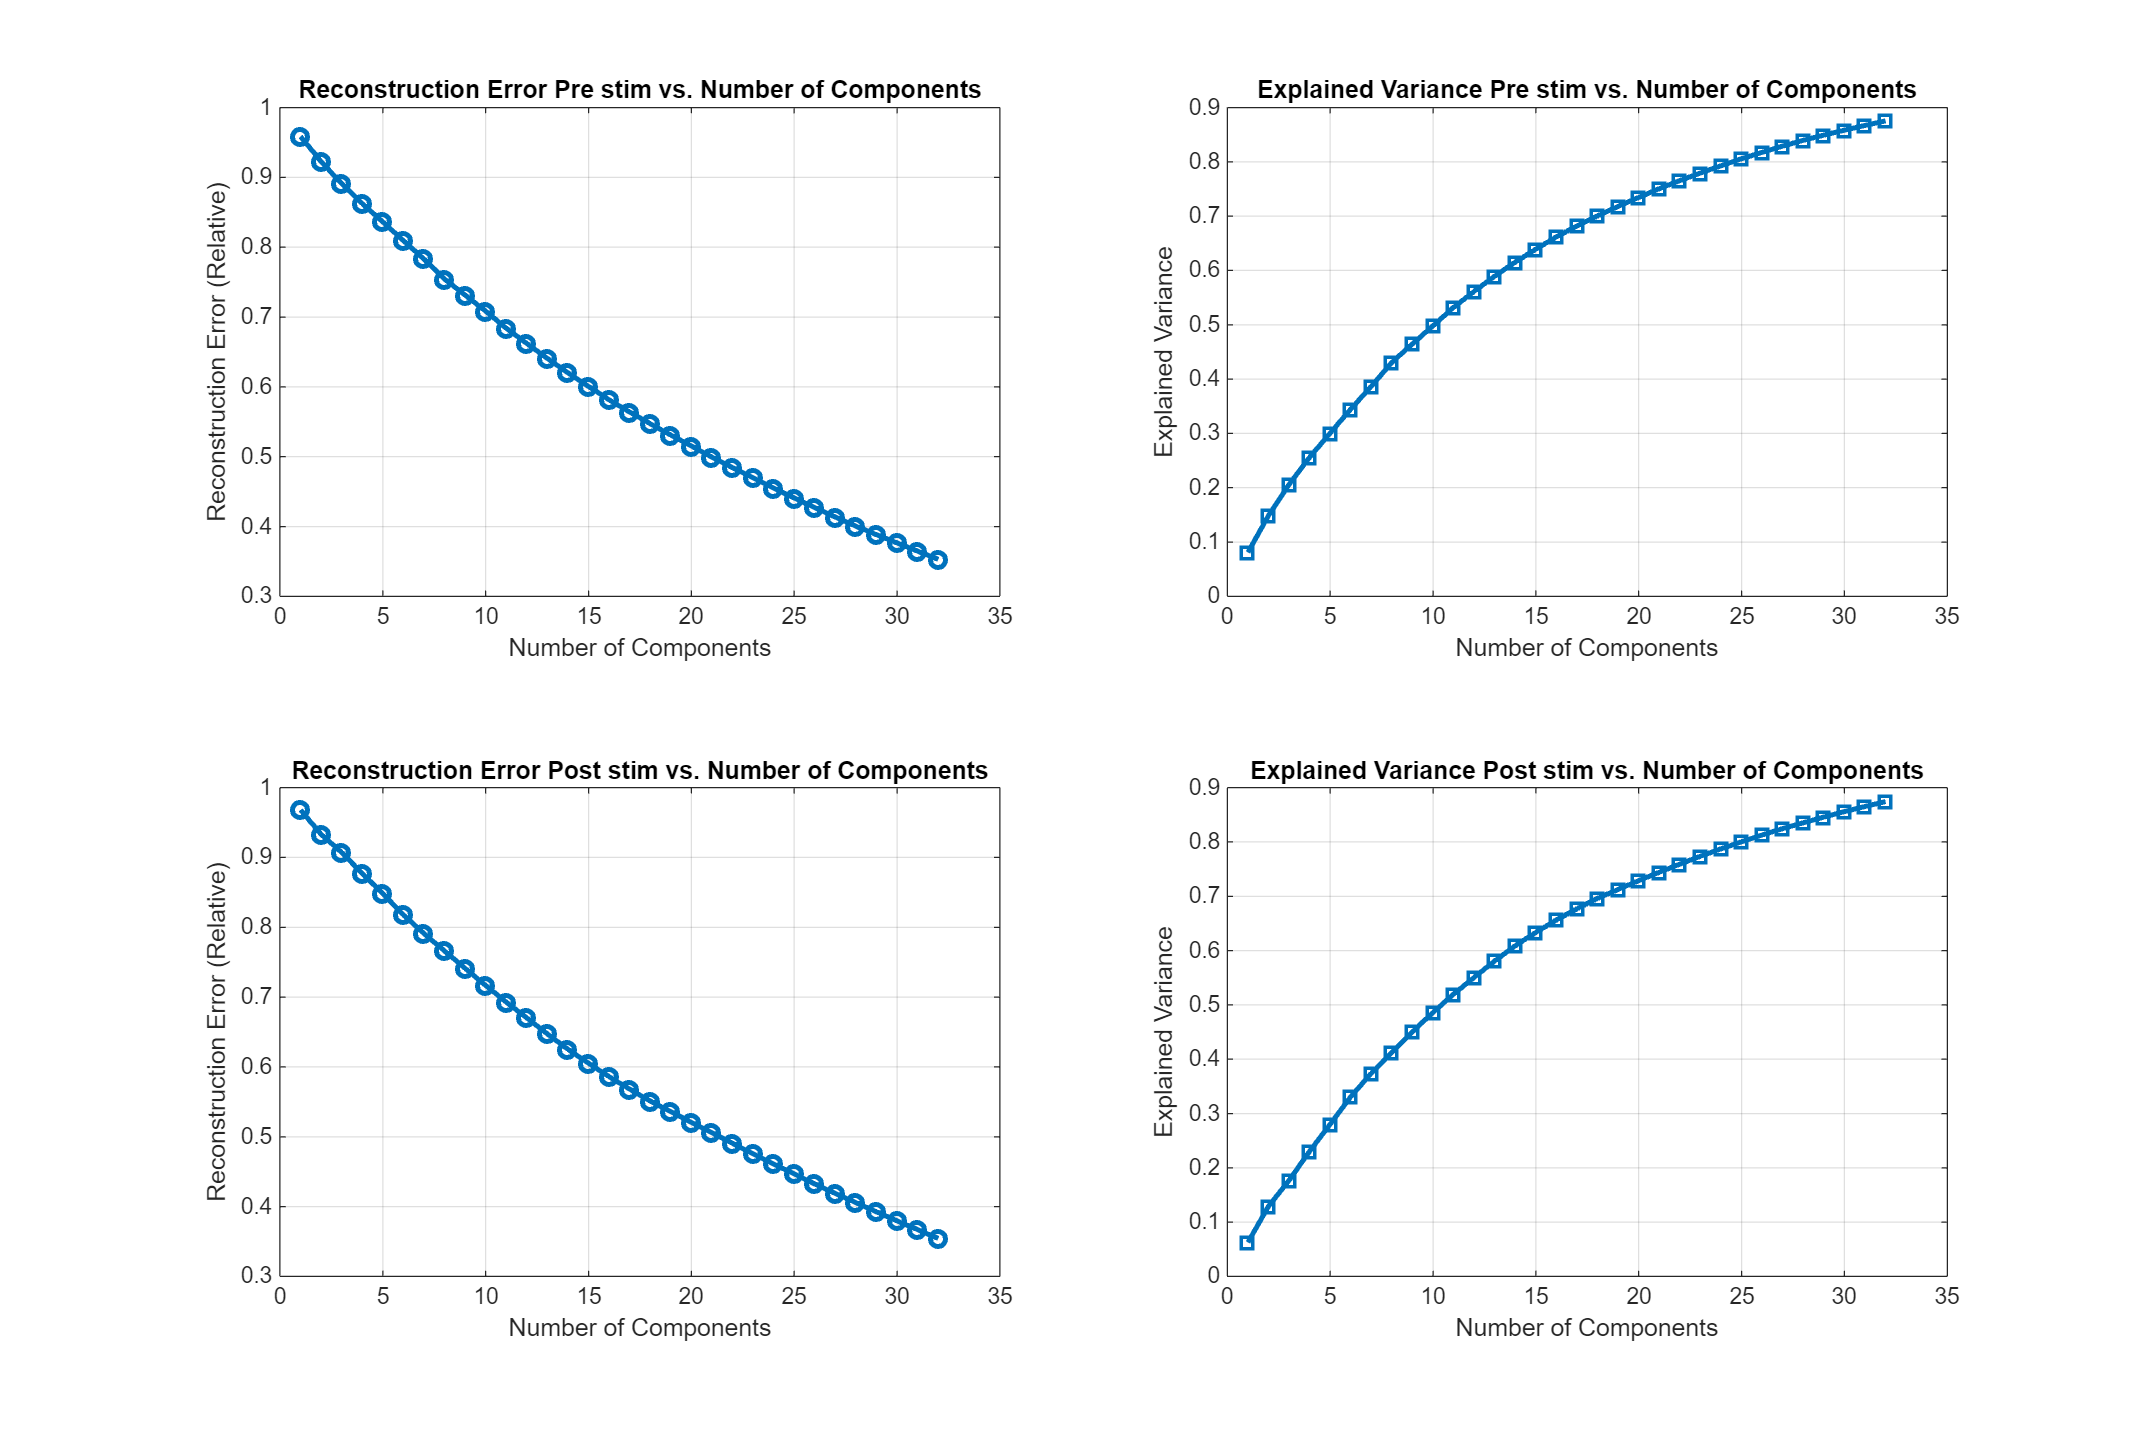

% Plot reconstruction error
figure('Position', [100, 100, 1500, 1000]); % [x, y, width, height]
subplot(2,2,1)
plot(num_components, reconstruction_errors_pre, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Pre stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,2)
plot(num_components, explained_variance_pre, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Pre stim vs. Number of Components');
grid on;

subplot(2,2,3)
plot(num_components, reconstruction_errors_post, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Post stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,4)
plot(num_components, explained_variance_post, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Post stim vs. Number of Components');
grid on;

threshold = 0.85;  % Target explained variance threshold

% Preallocate result
pc_at_85_pre = zeros(1, 1);
pc_at_85_post = zeros(1, 1);

pc_at_85_pre = find(round(explained_variance_pre,2) >= threshold, 1, 'first');
pc_at_85_post = find(round(explained_variance_post,2) >= threshold, 1, 'first'); 
disp(["num of PCs to get to 85% variance for pre-stim: ", pc_at_85_pre]);

    "num of PCs to get to 85% variance for pre-stim: "    "29"



disp(["num of PCs to get to 85% variance for post-stim: ", pc_at_85_post]);

    "num of PCs to get to 85% variance for post-stim: "    "29"



% Chosing to do TCA on the first 29 components since they explain 85% of
% the variance

% Tucker decomposition for pre-stimulus data
% Using the same rank k for all modes
k_pre = pc_at_85_pre;
tucker_ranks_pre = [k_pre, k_pre, k_pre];
tucker_pre = tucker_als(pre_tensor, tucker_ranks_pre, 'tol', 1e-4, 'maxiters', 50);


Tucker Alternating Least-Squares:
 Iter  1: fit = 6.116586e-01 fitdelta = 6.1e-01
 Iter  2: fit = 6.116586e-01 fitdelta = 7.2e-13



% Tucker decomposition for post-stimulus data
k_post = pc_at_85_post;
tucker_ranks_post = [k_post, k_post, k_post];
tucker_post = tucker_als(post_tensor, tucker_ranks_post, 'tol', 1e-4, 'maxiters', 50);


Tucker Alternating Least-Squares:
 Iter  1: fit = 6.073699e-01 fitdelta = 6.1e-01
 Iter  2: fit = 6.073699e-01 fitdelta = 4.3e-11


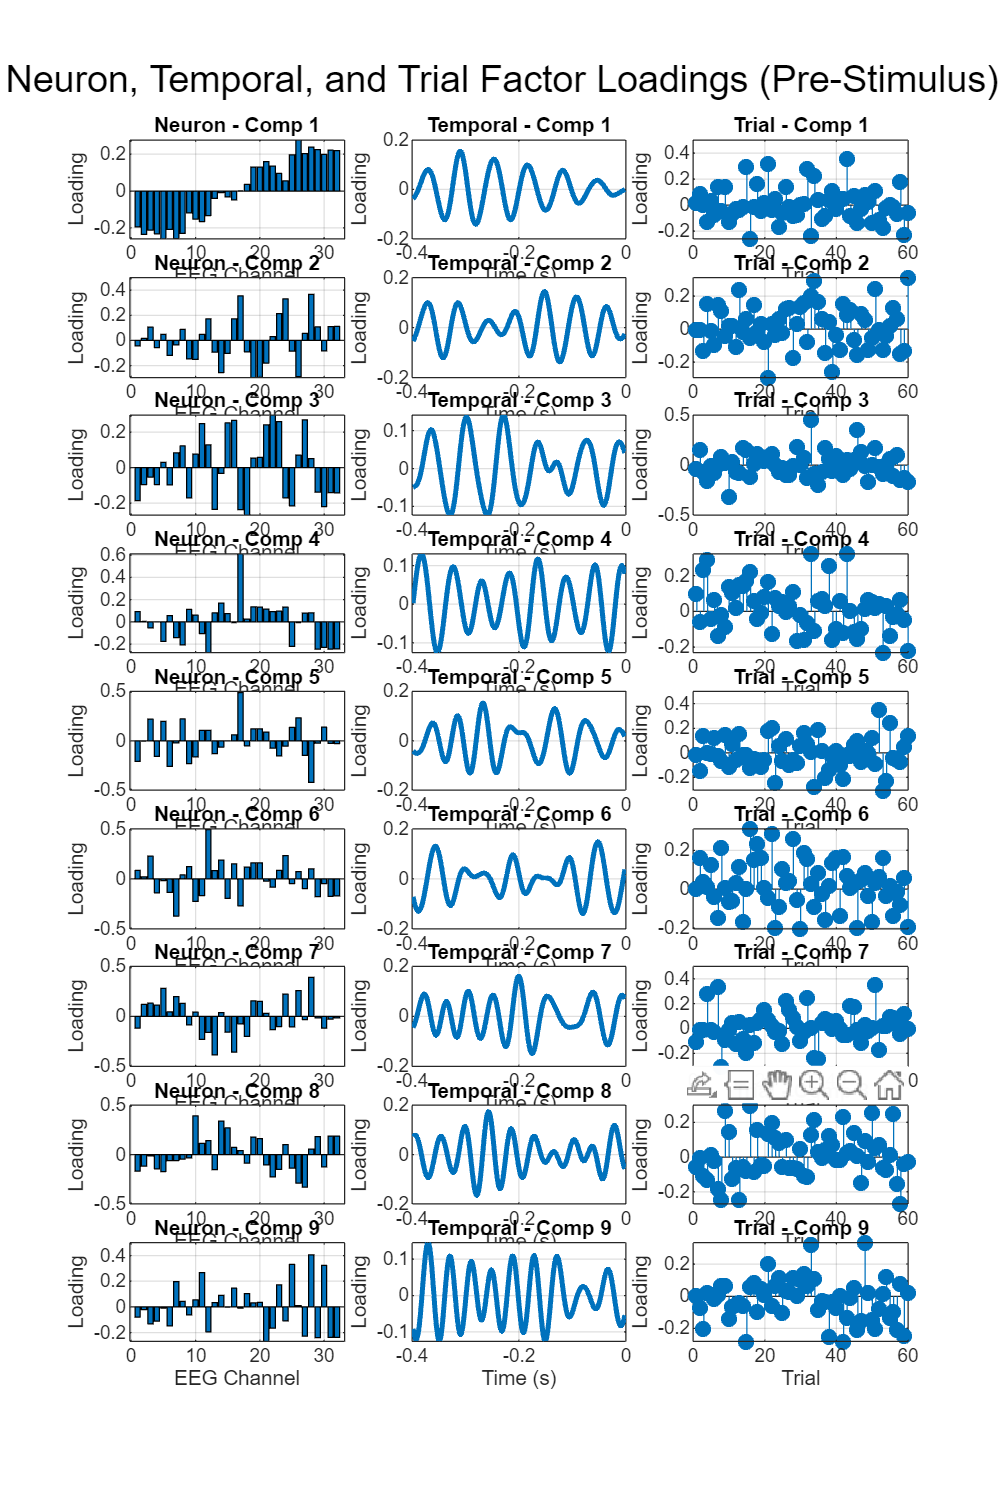

% Extract core tensor and factor matrices
core_tensor_pre = tucker_pre.core;
factor_matrices_pre = tucker_pre.U;

% Access individual factor matrices for each mode
channel_factors_pre = factor_matrices_pre{1}; % Channels
time_factors_pre = factor_matrices_pre{2}; % Time points
trial_factors_pre = factor_matrices_pre{3}; % Trials

figure('Position', [100, 100, 1200, 1800]);  % Adjust size for vertical layout

for comp = 1:9
    row = comp;

    % Channel factor (Column 1)
    subplot(9, 3, (row - 1)*3 + 1);
    bar(channel_factors_pre(:, comp));
    title(['Neuron - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    % Temporal factor (Column 2)
    subplot(9, 3, (row - 1)*3 + 2);
    plot(time_vector(pre_idx), time_factors_pre(:, comp), 'LineWidth', 2);
    title(['Temporal - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    % Trial factor (Column 3)
    subplot(9, 3, (row - 1)*3 + 3);
    stem(trial_factors_pre(:, comp), 'filled');
    title(['Trial - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end

sgtitle('Neuron, Temporal, and Trial Factor Loadings (Pre-Stimulus)');

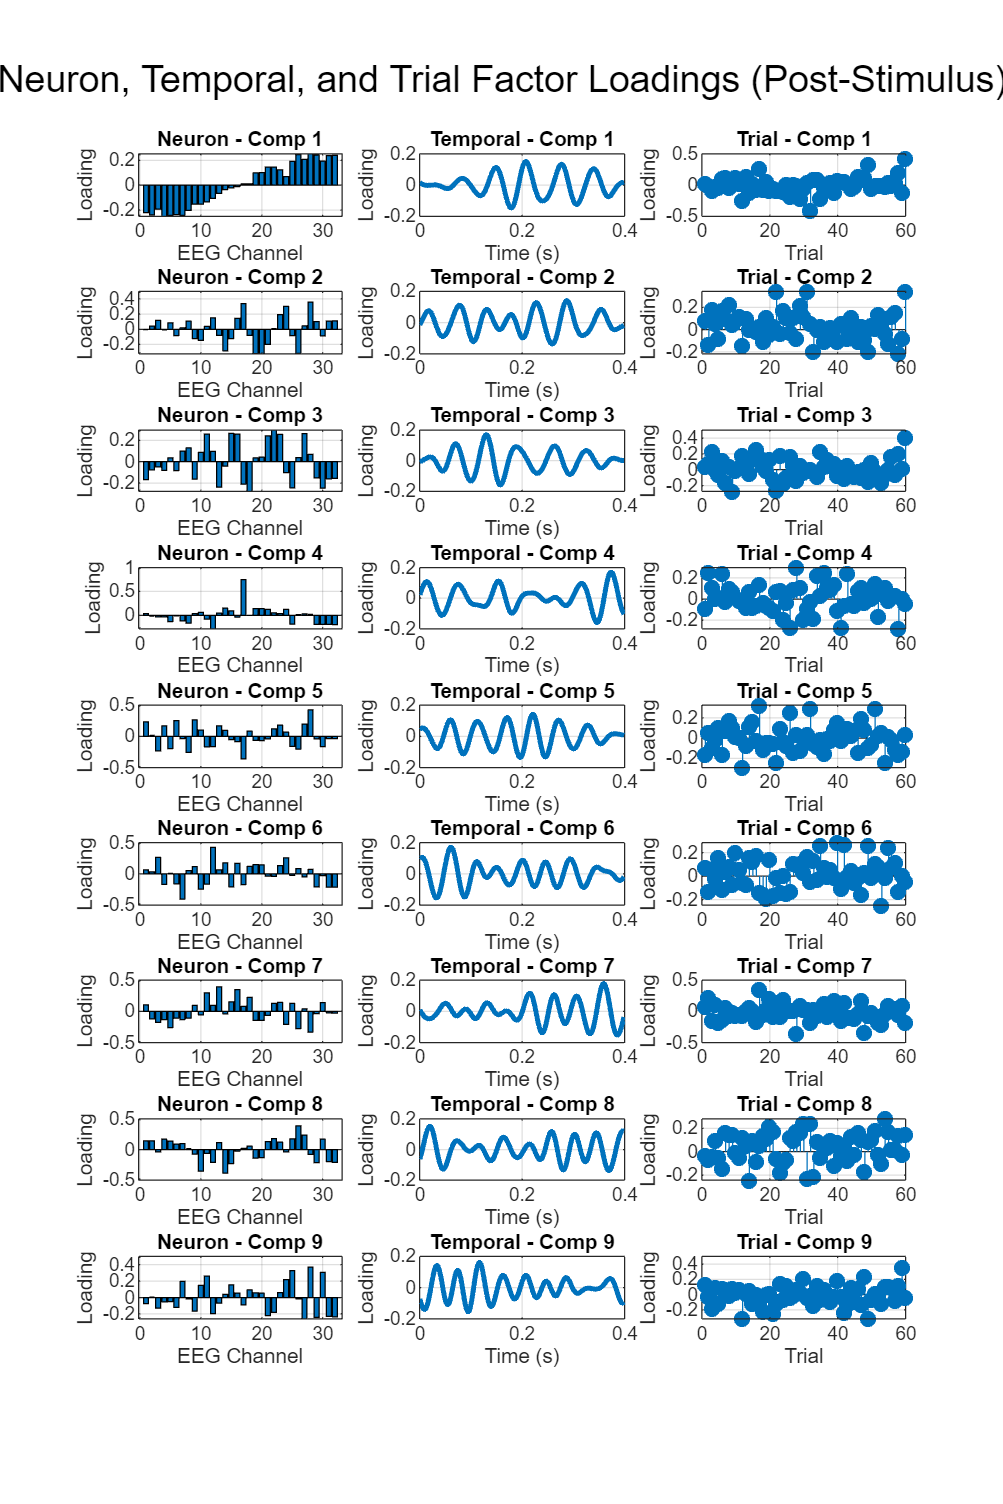

% Extract core tensor and factor matrices
core_tensor_post = tucker_post.core;
factor_matrices_post = tucker_post.U;

% Access individual factor matrices for each mode
channel_factors_post = factor_matrices_post{1}; % Channels
time_factors_post = factor_matrices_post{2}; % Time points
trial_factors_post = factor_matrices_post{3}; % Trials

figure('Position', [100, 100, 1200, 1800]);  % Adjust size for vertical layout

for comp = 1:9
    row = comp;

    % Channel factor (Column 1)
    subplot(9, 3, (row - 1)*3 + 1);
    bar(channel_factors_post(:, comp));
    title(['Neuron - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    % Temporal factor (Column 2)
    subplot(9, 3, (row - 1)*3 + 2);
    plot(time_vector(post_idx), time_factors_post(:, comp), 'LineWidth', 2);
    title(['Temporal - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    % Trial factor (Column 3)
    subplot(9, 3, (row - 1)*3 + 3);
    stem(trial_factors_post(:, comp), 'filled');
    title(['Trial - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end

sgtitle('Neuron, Temporal, and Trial Factor Loadings (Post-Stimulus)');

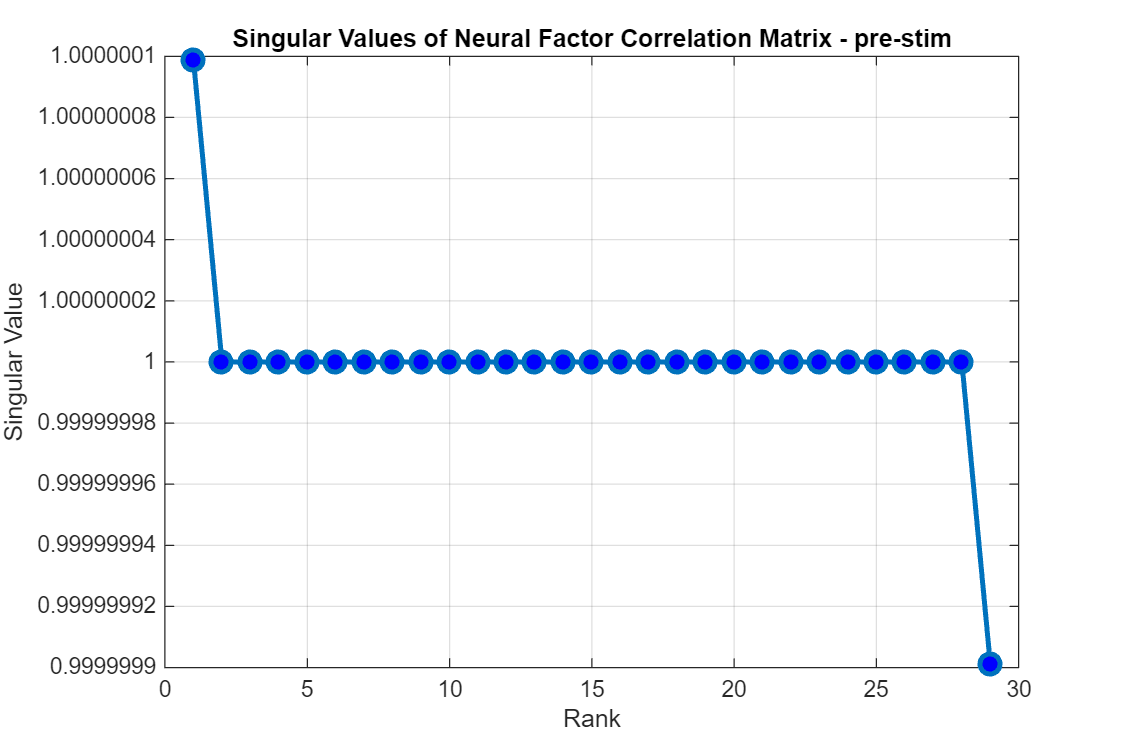

% Factor Analysis: The Channel factor correlation matrix

% Create correlation matrix for channel factor channel_factor
% Each column in channel_factor_pre represents a component, so we compute correlations between components
correlation_matrix_pre = corrcoef(channel_factors_pre);
% Apply SVD
[Un_pre, S_pre, V_pre] = svd(correlation_matrix_pre);

% Extract singular values (diagonal elements of S)
singular_values_pre = diag(S_pre);

% Plot singular values vs. rank
figure('Position', [100, 100, 600, 400]);
plot(1:length(singular_values_pre), singular_values_pre, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value');
title('Singular Values of Channel Factor Correlation Matrix - pre-stim');
grid on;

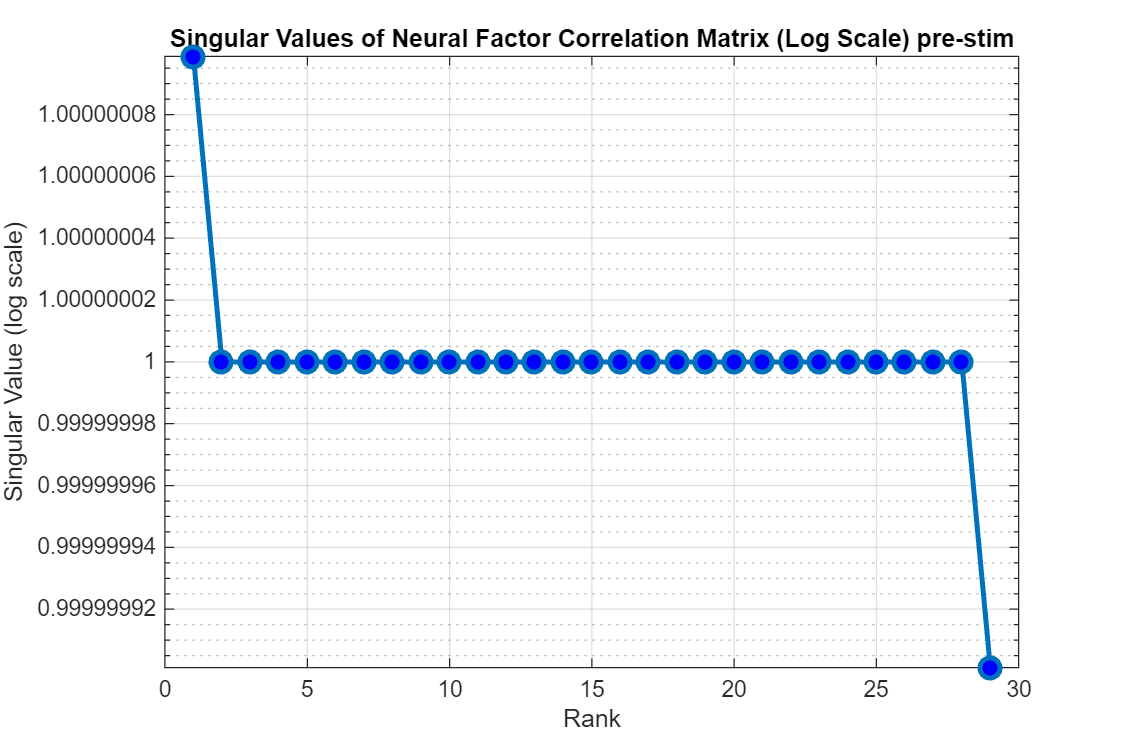

% Add log-scale version (often useful for seeing trend across all values)
figure('Position', [100, 100, 600, 400]);
semilogy(1:length(singular_values_pre), singular_values_pre, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value (log scale)');
title('Singular Values of Channel Factor Correlation Matrix (Log Scale) pre-stim');
grid on;

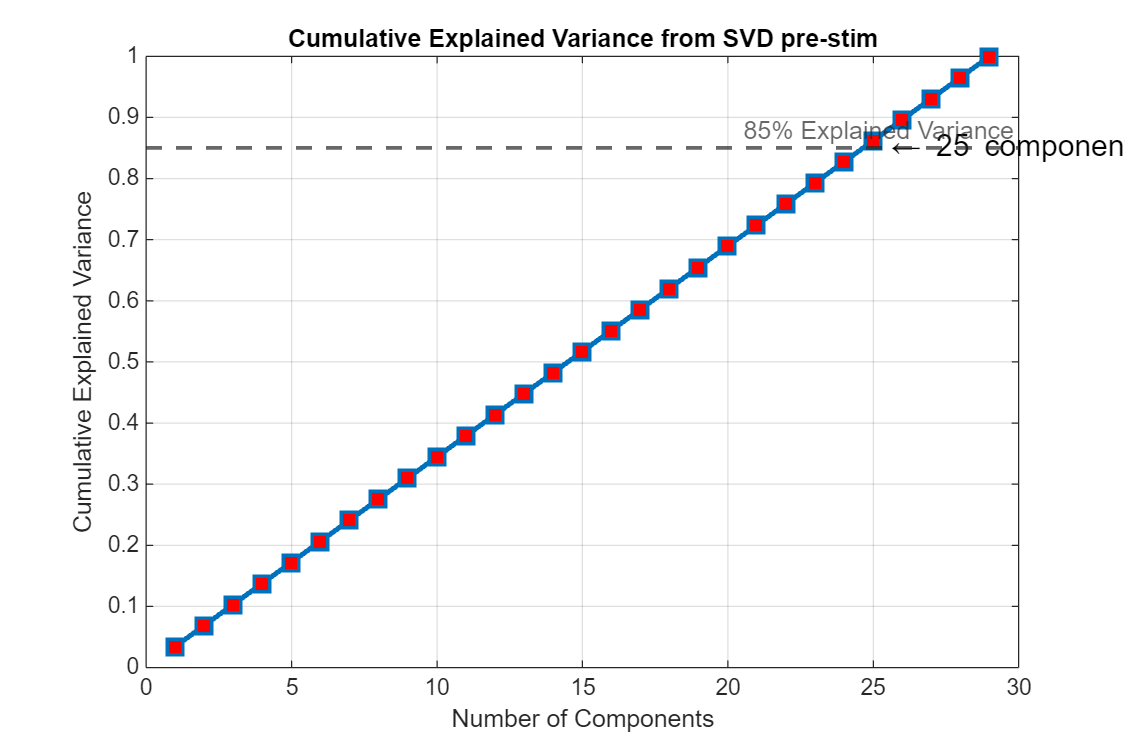

% Calculate cumulative explained variance
explained_variance_pre = singular_values_pre / sum(singular_values_pre);
cumulative_variance_pre = cumsum(explained_variance_pre);

% Plot cumulative explained variance
figure('Position', [100, 100, 600, 400]);
plot(1:length(cumulative_variance_pre), cumulative_variance_pre, 's-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;
% Add horizontal line at 90% explained variance
yline(0.85, '--', '85% Explained Variance', 'LineWidth', 1.5);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance from SVD pre-stim');
grid on;

% Find number of components needed to explain 90% of variance
components_85pct_pre = find(cumulative_variance_pre >= 0.85, 1);
text(components_85pct_pre + 0.5, 0.85, ['\leftarrow ' num2str(components_85pct_pre) ' components'], 'FontSize', 12);

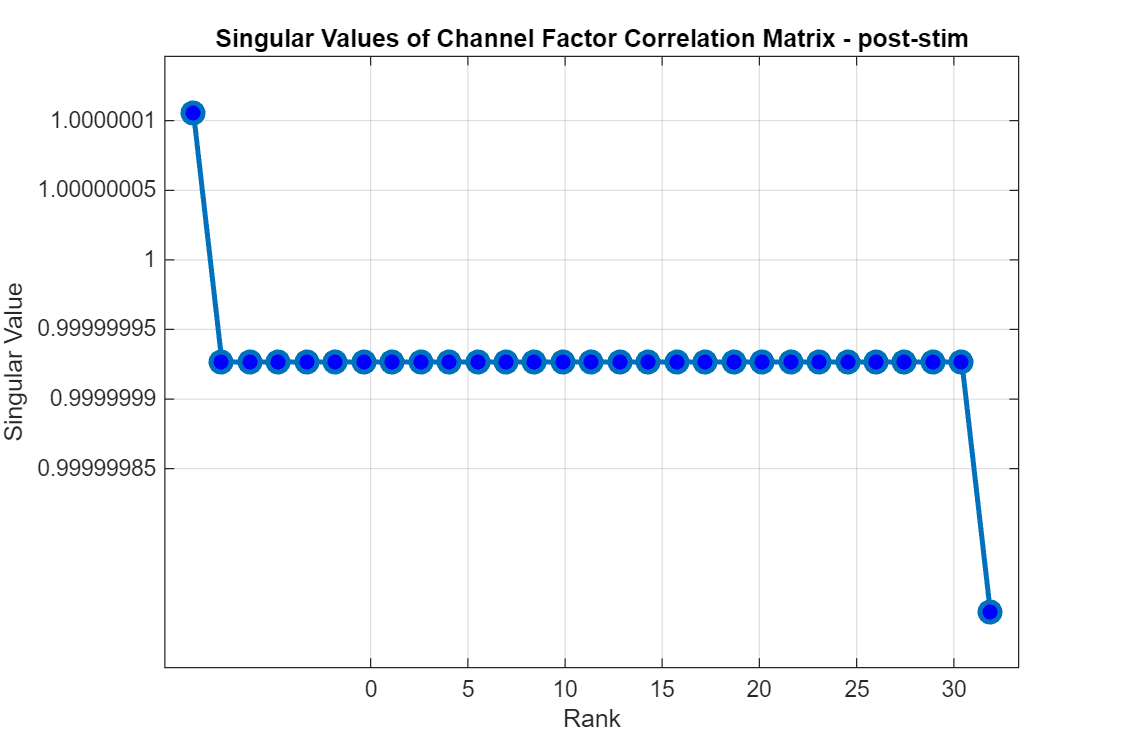

% Each column in channel_factor_pre represents a component, so we compute correlations between components
correlation_matrix_post = corrcoef(channel_factors_post);
% Apply SVD
[Un_post, S_post, V_post] = svd(correlation_matrix_post);

% Extract singular values (diagonal elements of S)
singular_values_post = diag(S_post);

% Plot singular values vs. rank
figure('Position', [100, 100, 600, 400]);
plot(1:length(singular_values_post), singular_values_post, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value');
title('Singular Values of Channel Factor Correlation Matrix - post-stim');
grid on;

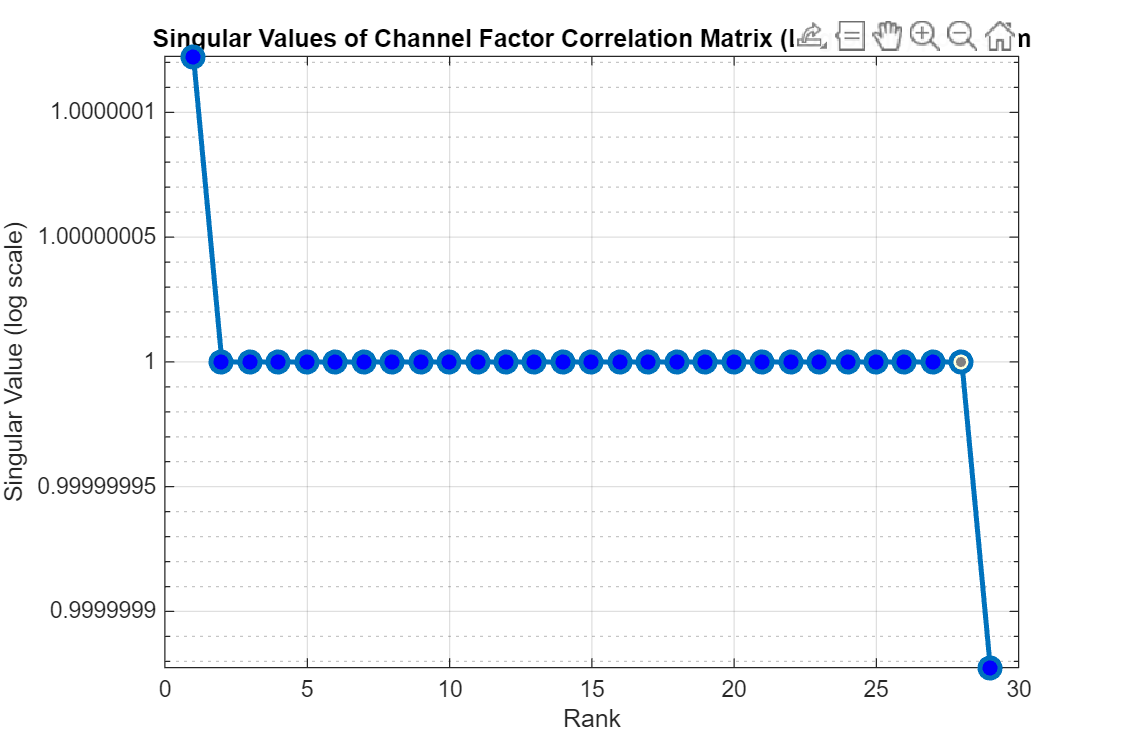

% Add log-scale version (often useful for seeing trend across all values)
figure('Position', [100, 100, 600, 400]);
semilogy(1:length(singular_values_post), singular_values_post, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value (log scale)');
title('Singular Values of Channel Factor Correlation Matrix (Log Scale) post-stim');
grid on;

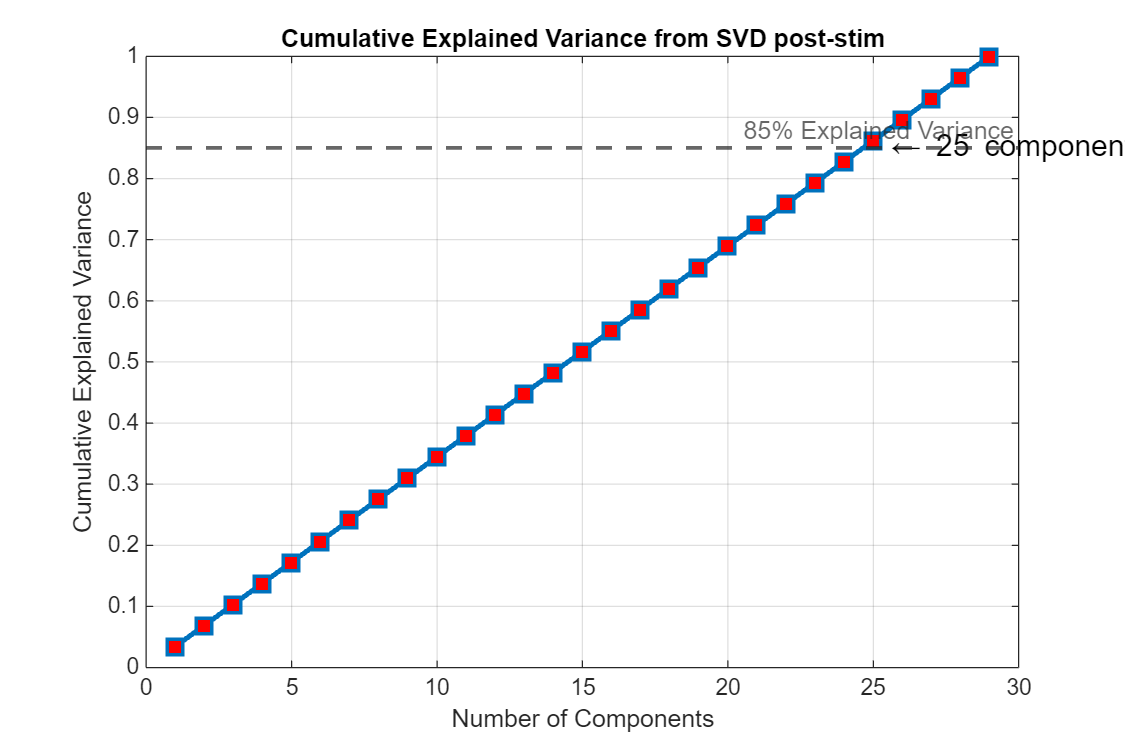

% Calculate cumulative explained variance
explained_variance_post = singular_values_post / sum(singular_values_post);
cumulative_variance_post = cumsum(explained_variance_post);

% Plot cumulative explained variance
figure('Position', [100, 100, 600, 400]);
plot(1:length(cumulative_variance_post), cumulative_variance_post, 's-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;
% Add horizontal line at 85% explained variance
yline(0.85, '--', '85% Explained Variance', 'LineWidth', 1.5);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance from SVD post-stim');
grid on;

% Find number of components needed to explain 85% of variance
components_85pct_post = find(cumulative_variance_post >= 0.85, 1);
text(components_85pct_post + 0.5, 0.85, ['\leftarrow ' num2str(components_85pct_post) ' components'], 'FontSize', 12);

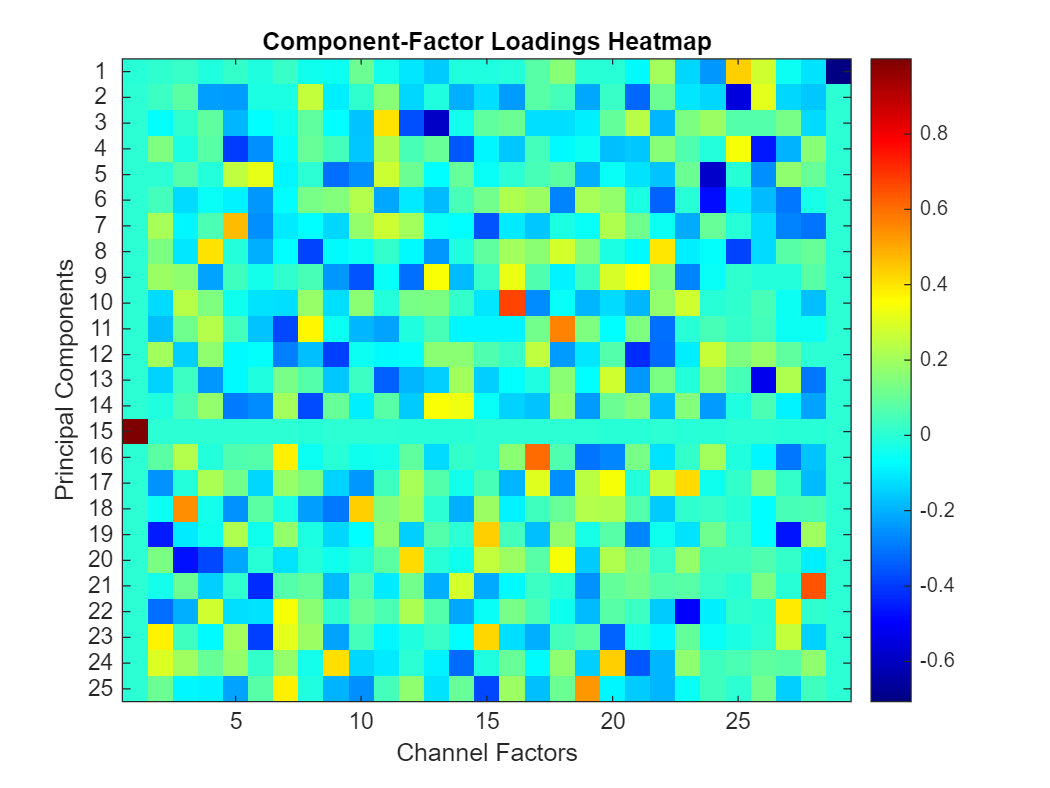

figure;
imagesc(V_pre(:,1:25)');  % Transpose to get components as rows
colormap(jet);
colorbar;
xlabel('Channel Factors');
ylabel('Principal Components');
title('Component-Factor Loadings Heatmap');
set(gca, 'YTick', 1:25, 'YTickLabel', {1:25});

for i = 1:25  % For each of your top 3 components
    [sortedValues_pre, sortedIndices_pre] = sort(abs(V_pre(:,i)), 'descend');
    fprintf('Principal Component %d - Top contributing factors:\n', i);
    for j = 1:min(10, length(sortedIndices_pre))  % Show top 10 factors
        fprintf('  Factor %d: Loading = %.4f\n', sortedIndices_pre(j), V_pre(sortedIndices_pre(j),i));
    end
    fprintf('\n');
end

Principal Component 1 - Top contributing factors:


  Factor 29: Loading = -0.7071
  Factor 25: Loading = 0.4381
  Factor 26: Loading = 0.2780
  Factor 24: Loading = -0.2435
  Factor 22: Loading = 0.2044
  Factor 18: Loading = 0.1560
  Factor 13: Loading = -0.1552
  Factor 23: Loading = -0.1376
  Factor 28: Loading = -0.1171
  Factor 12: Loading = -0.1128


Principal Component 2 - Top contributing factors:


  Factor 25: Loading = -0.5512
  Factor 21: Loading = -0.3266
  Factor 26: Loading = 0.3129
  Factor 8: Loading = 0.2567
  Factor 16: Loading = -0.2390
  Factor 5: Loading = -0.2375
  Factor 4: Loading = -0.2301
  Factor 19: Loading = -0.2139
  Factor 14: Loading = -0.2031
  Factor 28: Loading = -0.1617


Principal Component 3 - Top contributing factors:


  Factor 13: Loading = -0.5877
  Factor 11: Loading = 0.4062
  Factor 12: Loading = -0.3626
  Factor 21: Loading = 0.2332
  Factor 22: Loading = -0.1905
  Factor 24: Loading = 0.1901
  Factor 5: Loading = -0.1874
  Factor 10: Loading = -0.1685
  Factor 23: Loading = 0.1365
  Factor 28: Loading = -0.1321


Principal Component 4 - Top contributing factors:


  Factor 26: Loading = -0.4548
  Factor 5: Loading = -0.3969
  Factor 14: Loading = -0.3518
  Factor 25: Loading = 0.3414
  Factor 6: Loading = -0.2573
  Factor 11: Loading = 0.2194
  Factor 27: Loading = -0.1995
  Factor 20: Loading = -0.1783
  Factor 16: Loading = -0.1667
  Factor 10: Loading = -0.1654


Principal Component 5 - Top contributing factors:


  Factor 24: Loading = -0.5862
  Factor 6: Loading = 0.3136
  Factor 9: Loading = -0.3095
  Factor 11: Loading = 0.2699
  Factor 10: Loading = -0.2600
  Factor 26: Loading = -0.2550
  Factor 5: Loading = 0.2502
  Factor 19: Loading = -0.2061
  Factor 27: Loading = 0.1729
  Factor 22: Loading = -0.1722


Principal Component 6 - Top contributing factors:


  Factor 24: Loading = -0.4781
  Factor 22: Loading = -0.3274
  Factor 27: Loading = -0.2958
  Factor 18: Loading = -0.2748
  Factor 6: Loading = -0.2408
  Factor 10: Loading = 0.2314
  Factor 16: Loading = 0.2203
  Factor 11: Loading = -0.2192
  Factor 19: Loading = 0.2093
  Factor 17: Loading = 0.1888


Principal Component 7 - Top contributing factors:


  Factor 5: Loading = 0.4684
  Factor 15: Loading = -0.3538
  Factor 28: Loading = -0.3017
  Factor 27: Loading = -0.2793
  Factor 11: Loading = 0.2698
  Factor 6: Loading = -0.2580
  Factor 20: Loading = 0.2240
  Factor 2: Loading = 0.2097
  Factor 23: Loading = -0.2091
  Factor 12: Loading = 0.2042


Principal Component 8 - Top contributing factors:


  Factor 4: Loading = 0.4054
  Factor 22: Loading = 0.3981
  Factor 25: Loading = -0.3842
  Factor 8: Loading = -0.3812
  Factor 18: Loading = 0.2849
  Factor 13: Loading = -0.2410
  Factor 6: Loading = -0.2017
  Factor 16: Loading = 0.2013
  Factor 17: Loading = 0.1611
  Factor 19: Loading = 0.1540


Principal Component 9 - Top contributing factors:


  Factor 21: Loading = 0.3557
  Factor 10: Loading = -0.3544
  Factor 13: Loading = 0.3512
  Factor 16: Loading = 0.3228
  Factor 12: Loading = -0.3134
  Factor 20: Loading = 0.2927
  Factor 23: Loading = -0.2742
  Factor 9: Loading = -0.2450
  Factor 4: Loading = -0.2227
  Factor 2: Loading = 0.1880


Principal Component 10 - Top contributing factors:


  Factor 16: Loading = 0.6679
  Factor 23: Loading = 0.2764
  Factor 17: Loading = -0.2669
  Factor 3: Loading = 0.2394
  Factor 19: Loading = -0.1890
  Factor 21: Loading = -0.1874
  Factor 8: Loading = 0.1805
  Factor 28: Loading = -0.1761
  Factor 22: Loading = 0.1736
  Factor 10: Loading = 0.1648


Principal Component 11 - Top contributing factors:


  Factor 18: Loading = 0.5621
  Factor 7: Loading = -0.3738
  Factor 8: Loading = 0.3703
  Factor 22: Loading = -0.3120
  Factor 4: Loading = 0.2317
  Factor 11: Loading = -0.2207
  Factor 10: Loading = -0.1914
  Factor 2: Loading = -0.1748
  Factor 6: Loading = -0.1699
  Factor 19: Loading = 0.1441


Principal Component 12 - Top contributing factors:


  Factor 21: Loading = -0.4269
  Factor 9: Loading = -0.3924
  Factor 22: Loading = -0.3201
  Factor 7: Loading = -0.2806
  Factor 24: Loading = 0.2651
  Factor 17: Loading = 0.2496
  Factor 18: Loading = -0.2367
  Factor 2: Loading = 0.2052
  Factor 26: Loading = 0.1800
  Factor 8: Loading = -0.1744


Principal Component 13 - Top contributing factors:


  Factor 26: Loading = -0.5232
  Factor 11: Loading = -0.3339
  Factor 28: Loading = -0.2942
  Factor 20: Loading = 0.2786
  Factor 21: Loading = -0.2430
  Factor 4: Loading = -0.2404
  Factor 27: Loading = 0.2214
  Factor 14: Loading = 0.2022
  Factor 12: Loading = -0.1890
  Factor 18: Loading = 0.1634


Principal Component 14 - Top contributing factors:


  Factor 8: Loading = -0.3687
  Factor 13: Loading = 0.3527
  Factor 14: Loading = 0.3293
  Factor 5: Loading = -0.2928
  Factor 6: Loading = -0.2615
  Factor 24: Loading = -0.2358
  Factor 19: Loading = -0.2337
  Factor 28: Loading = -0.2241
  Factor 7: Loading = 0.2062
  Factor 22: Loading = -0.1827


Principal Component 15 - Top contributing factors:


  Factor 1: Loading = 1.0000
  Factor 25: Loading = 0.0047
  Factor 28: Loading = -0.0036
  Factor 24: Loading = -0.0027
  Factor 26: Loading = 0.0025
  Factor 22: Loading = 0.0019
  Factor 23: Loading = -0.0017
  Factor 18: Loading = 0.0017
  Factor 12: Loading = -0.0017
  Factor 6: Loading = 0.0013


Principal Component 16 - Top contributing factors:


  Factor 17: Loading = 0.6023
  Factor 7: Loading = 0.3824
  Factor 19: Loading = -0.3023
  Factor 27: Loading = -0.2963
  Factor 20: Loading = -0.2735
  Factor 3: Loading = 0.2265
  Factor 24: Loading = 0.2035
  Factor 28: Loading = -0.1678
  Factor 16: Loading = 0.1654
  Factor 13: Loading = -0.1297


Principal Component 17 - Top contributing factors:


  Factor 23: Loading = 0.4198
  Factor 20: Loading = 0.3425
  Factor 17: Loading = 0.3032
  Factor 18: Loading = -0.2568
  Factor 22: Loading = 0.2541
  Factor 2: Loading = -0.2516
  Factor 19: Loading = 0.2453
  Factor 10: Loading = -0.2419
  Factor 4: Loading = 0.2152
  Factor 12: Loading = 0.2114


Principal Component 18 - Top contributing factors:


  Factor 3: Loading = 0.5451
  Factor 10: Loading = 0.4350
  Factor 9: Loading = -0.2954
  Factor 5: Loading = -0.2480
  Factor 8: Loading = -0.2318
  Factor 19: Loading = 0.2306
  Factor 20: Loading = 0.2260
  Factor 14: Loading = -0.2010
  Factor 12: Loading = 0.1957
  Factor 15: Loading = 0.1879


Principal Component 19 - Top contributing factors:


  Factor 27: Loading = -0.4652
  Factor 2: Loading = -0.4481
  Factor 15: Loading = 0.4377
  Factor 21: Loading = -0.2714
  Factor 5: Loading = 0.2218
  Factor 28: Loading = 0.1933
  Factor 7: Loading = 0.1794
  Factor 17: Loading = -0.1743
  Factor 11: Loading = 0.1730
  Factor 18: Loading = 0.1697


Principal Component 20 - Top contributing factors:


  Factor 3: Loading = -0.4735
  Factor 12: Loading = 0.4185
  Factor 4: Loading = -0.3742
  Factor 18: Loading = 0.3454
  Factor 15: Loading = 0.2558
  Factor 20: Loading = 0.2240
  Factor 5: Loading = -0.2171
  Factor 16: Loading = 0.1886
  Factor 23: Loading = 0.1796
  Factor 19: Loading = -0.1582


Principal Component 21 - Top contributing factors:


  Factor 28: Loading = 0.6462
  Factor 6: Loading = -0.4267
  Factor 14: Loading = 0.2853
  Factor 19: Loading = -0.2479
  Factor 15: Loading = -0.2122
  Factor 13: Loading = -0.2014
  Factor 9: Loading = -0.1807
  Factor 4: Loading = -0.1505
  Factor 26: Loading = 0.1339
  Factor 12: Loading = 0.1241


Principal Component 22 - Top contributing factors:


  Factor 23: Loading = -0.4961
  Factor 27: Loading = 0.3910
  Factor 7: Loading = 0.3448
  Factor 2: Loading = -0.3074
  Factor 4: Loading = 0.2760
  Factor 12: Loading = 0.2181
  Factor 14: Loading = -0.2179
  Factor 3: Loading = -0.2028
  Factor 19: Loading = -0.1858
  Factor 8: Loading = 0.1598


Principal Component 23 - Top contributing factors:


  Factor 15: Loading = 0.4217
  Factor 6: Loading = -0.3882
  Factor 2: Loading = 0.3776
  Factor 20: Loading = -0.3320
  Factor 7: Loading = 0.3094
  Factor 27: Loading = 0.2564
  Factor 9: Loading = -0.2265
  Factor 5: Loading = 0.2056
  Factor 17: Loading = -0.2047
  Factor 8: Loading = 0.1891


Principal Component 24 - Top contributing factors:


  Factor 20: Loading = 0.4349
  Factor 9: Loading = 0.4123
  Factor 21: Loading = -0.3495
  Factor 14: Loading = -0.3166
  Factor 2: Loading = 0.2978
  Factor 3: Loading = 0.1982
  Factor 22: Loading = -0.1891
  Factor 5: Loading = 0.1796
  Factor 7: Loading = 0.1752
  Factor 18: Loading = 0.1703


Principal Component 25 - Top contributing factors:


  Factor 19: Loading = 0.5289
  Factor 7: Loading = 0.3807
  Factor 15: Loading = -0.3770
  Factor 10: Loading = -0.2594
  Factor 5: Loading = -0.2205
  Factor 9: Loading = -0.1972
  Factor 22: Loading = -0.1920
  Factor 16: Loading = 0.1895
  Factor 17: Loading = -0.1772
  Factor 12: Loading = 0.1680


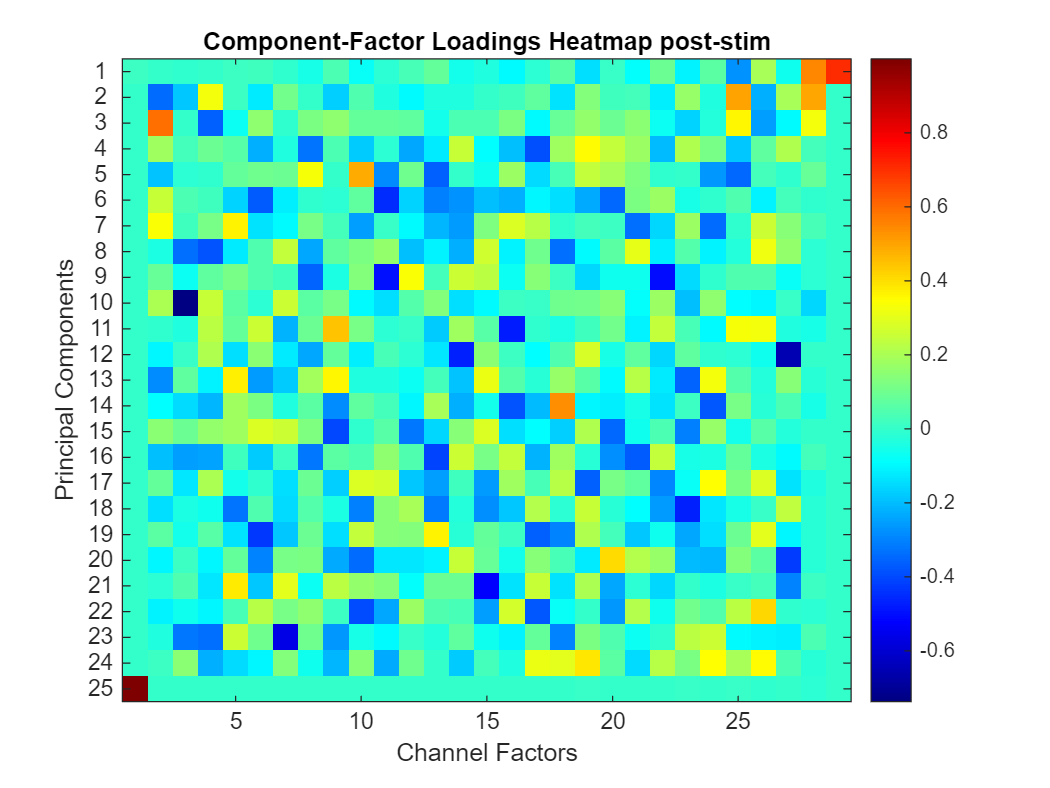

figure;
imagesc(V_post(:,1:25)');  % Transpose to get components as rows
colormap(jet);
colorbar;
xlabel('Channel Factors');
ylabel('Principal Components');
title('Component-Factor Loadings Heatmap post-stim');
set(gca, 'YTick', 1:25, 'YTickLabel', {1:25});

for i = 1:25  % For each of your top 3 components
    [sortedValues_post, sortedIndices_post] = sort(abs(V_post(:,i)), 'descend');
    fprintf('Principal Component %d - Top contributing factors:\n', i);
    for j = 1:min(10, length(sortedIndices_post))  % Show top 10 factors
        fprintf('  Factor %d: Loading = %.4f\n', sortedIndices_post(j), V_post(sortedIndices_post(j),i));
    end
    fprintf('\n');
end

Principal Component 1 - Top contributing factors:


  Factor 29: Loading = 0.7071
  Factor 28: Loading = 0.5459
  Factor 25: Loading = -0.2694
  Factor 26: Loading = 0.1946
  Factor 19: Loading = -0.1406
  Factor 23: Loading = -0.1098
  Factor 16: Loading = -0.0982
  Factor 22: Loading = 0.0940
  Factor 13: Loading = 0.0810
  Factor 21: Loading = -0.0805


Principal Component 2 - Top contributing factors:


  Factor 25: Loading = 0.4997
  Factor 28: Loading = 0.4970
  Factor 2: Loading = -0.3404
  Factor 4: Loading = 0.3260
  Factor 26: Loading = -0.2229
  Factor 27: Loading = 0.1983
  Factor 3: Loading = -0.1865
  Factor 23: Loading = 0.1718
  Factor 9: Loading = -0.1685
  Factor 19: Loading = 0.1354


Principal Component 3 - Top contributing factors:


  Factor 2: Loading = 0.5921
  Factor 25: Loading = 0.3587
  Factor 4: Loading = -0.3579
  Factor 28: Loading = 0.3266
  Factor 26: Loading = -0.2522
  Factor 23: Loading = -0.1638
  Factor 19: Loading = 0.1598
  Factor 6: Loading = 0.1555
  Factor 9: Loading = 0.1551
  Factor 21: Loading = 0.1517


Principal Component 4 - Top contributing factors:


  Factor 17: Loading = -0.3900
  Factor 19: Loading = 0.3523
  Factor 8: Loading = -0.3265
  Factor 14: Loading = 0.2526
  Factor 20: Loading = 0.2409
  Factor 12: Loading = -0.2386
  Factor 6: Loading = -0.2275
  Factor 27: Loading = 0.2106
  Factor 23: Loading = 0.2100
  Factor 22: Loading = -0.2051


Principal Component 5 - Top contributing factors:


  Factor 10: Loading = 0.4862
  Factor 13: Loading = -0.3576
  Factor 25: Loading = -0.3469
  Factor 8: Loading = 0.3329
  Factor 11: Loading = -0.2869
  Factor 24: Loading = -0.2637
  Factor 19: Loading = 0.2443
  Factor 20: Loading = 0.1939
  Factor 2: Loading = -0.1933
  Factor 16: Loading = 0.1772


Principal Component 6 - Top contributing factors:


  Factor 11: Loading = -0.4471
  Factor 6: Loading = -0.3704
  Factor 20: Loading = -0.3450
  Factor 13: Loading = -0.3029
  Factor 14: Loading = -0.2756
  Factor 2: Loading = 0.2482
  Factor 19: Loading = -0.2330
  Factor 16: Loading = -0.2257
  Factor 15: Loading = -0.2004
  Factor 22: Loading = 0.1746


Principal Component 7 - Top contributing factors:


  Factor 5: Loading = 0.3643
  Factor 24: Loading = -0.3408
  Factor 2: Loading = 0.3366
  Factor 21: Loading = -0.3303
  Factor 16: Loading = 0.2845
  Factor 14: Loading = -0.2583
  Factor 26: Loading = 0.2542
  Factor 10: Loading = -0.2493
  Factor 17: Loading = 0.2236
  Factor 13: Loading = -0.2142


Principal Component 8 - Top contributing factors:


  Factor 4: Loading = -0.3790
  Factor 18: Loading = -0.3348
  Factor 3: Loading = -0.3315
  Factor 26: Loading = 0.3213
  Factor 21: Loading = 0.3043
  Factor 15: Loading = 0.2648
  Factor 7: Loading = 0.2420
  Factor 8: Loading = -0.2362
  Factor 14: Loading = -0.2242
  Factor 12: Loading = -0.1948


Principal Component 9 - Top contributing factors:


  Factor 22: Loading = -0.5028
  Factor 11: Loading = -0.4942
  Factor 8: Loading = -0.3504
  Factor 12: Loading = 0.3408
  Factor 14: Loading = 0.2544
  Factor 15: Loading = 0.2321
  Factor 19: Loading = -0.1603
  Factor 23: Loading = -0.1510
  Factor 17: Loading = 0.1405
  Factor 10: Loading = 0.1377


Principal Component 10 - Top contributing factors:


  Factor 3: Loading = -0.7371
  Factor 7: Loading = 0.2589
  Factor 4: Loading = 0.2478
  Factor 2: Loading = 0.2016
  Factor 23: Loading = -0.2004
  Factor 22: Loading = 0.1769
  Factor 28: Loading = -0.1597
  Factor 24: Loading = 0.1536
  Factor 11: Loading = -0.1411
  Factor 14: Loading = -0.1406


Principal Component 11 - Top contributing factors:


  Factor 16: Loading = -0.4730
  Factor 9: Loading = 0.4487
  Factor 25: Loading = 0.3326
  Factor 26: Loading = 0.3226
  Factor 6: Loading = 0.2572
  Factor 22: Loading = 0.2449
  Factor 4: Loading = 0.2322
  Factor 7: Loading = -0.2166
  Factor 14: Loading = 0.1812
  Factor 13: Loading = -0.1742


Principal Component 12 - Top contributing factors:


  Factor 27: Loading = -0.6516
  Factor 14: Loading = -0.4695
  Factor 19: Loading = 0.2752
  Factor 8: Loading = -0.2381
  Factor 4: Loading = 0.2081
  Factor 22: Loading = -0.1546
  Factor 15: Loading = 0.1500
  Factor 6: Loading = 0.1487
  Factor 5: Loading = -0.1405
  Factor 13: Loading = -0.1309


Principal Component 13 - Top contributing factors:


  Factor 5: Loading = 0.3729
  Factor 9: Loading = 0.3577
  Factor 23: Loading = -0.3518
  Factor 24: Loading = 0.3274
  Factor 15: Loading = 0.3079
  Factor 2: Loading = -0.2830
  Factor 6: Loading = -0.2576
  Factor 21: Loading = 0.2228
  Factor 8: Loading = 0.1916
  Factor 14: Loading = -0.1875


Principal Component 14 - Top contributing factors:


  Factor 18: Loading = 0.5368
  Factor 16: Loading = -0.3806
  Factor 24: Loading = -0.3764
  Factor 9: Loading = -0.2881
  Factor 14: Loading = -0.2232
  Factor 4: Loading = -0.2106
  Factor 17: Loading = -0.2051
  Factor 13: Loading = 0.1972
  Factor 5: Loading = 0.1835
  Factor 3: Loading = -0.1505


Principal Component 15 - Top contributing factors:


  Factor 9: Loading = -0.3996
  Factor 20: Loading = -0.3451
  Factor 12: Loading = -0.3222
  Factor 23: Loading = -0.3040
  Factor 6: Loading = 0.2848
  Factor 15: Loading = 0.2815
  Factor 7: Loading = 0.2564
  Factor 19: Loading = 0.2092
  Factor 5: Loading = 0.1841
  Factor 24: Loading = 0.1689


Principal Component 16 - Top contributing factors:


  Factor 13: Loading = -0.4054
  Factor 21: Loading = -0.3647
  Factor 8: Loading = -0.3174
  Factor 20: Loading = -0.2770
  Factor 14: Loading = 0.2554
  Factor 3: Loading = -0.2509
  Factor 4: Loading = -0.2452
  Factor 16: Loading = 0.2427
  Factor 22: Loading = 0.2408
  Factor 17: Loading = -0.2203


Principal Component 17 - Top contributing factors:


  Factor 19: Loading = -0.3582
  Factor 24: Loading = 0.3485
  Factor 22: Loading = -0.2895
  Factor 26: Loading = 0.2826
  Factor 10: Loading = 0.2819
  Factor 11: Loading = 0.2695
  Factor 15: Loading = -0.2619
  Factor 13: Loading = -0.2503
  Factor 18: Loading = 0.2201
  Factor 4: Loading = 0.1995


Principal Component 18 - Top contributing factors:


  Factor 23: Loading = -0.4677
  Factor 5: Loading = -0.3295
  Factor 13: Loading = -0.3105
  Factor 10: Loading = -0.3079
  Factor 15: Loading = -0.2761
  Factor 22: Loading = -0.2603
  Factor 19: Loading = 0.2493
  Factor 27: Loading = 0.2344
  Factor 17: Loading = 0.2147
  Factor 12: Loading = 0.1955


Principal Component 19 - Top contributing factors:


  Factor 6: Loading = -0.4299
  Factor 13: Loading = 0.3632
  Factor 17: Loading = -0.3575
  Factor 26: Loading = 0.2985
  Factor 18: Loading = -0.2982
  Factor 10: Loading = 0.2445
  Factor 23: Loading = -0.2373
  Factor 19: Loading = 0.2081
  Factor 7: Loading = -0.1873
  Factor 21: Loading = -0.1810


Principal Component 20 - Top contributing factors:


  Factor 27: Loading = -0.4216
  Factor 20: Loading = 0.4080
  Factor 10: Loading = -0.3423
  Factor 6: Loading = -0.2976
  Factor 14: Loading = 0.2513
  Factor 9: Loading = -0.2309
  Factor 21: Loading = 0.2183
  Factor 24: Loading = -0.2138
  Factor 23: Loading = -0.2037
  Factor 22: Loading = 0.1657


Principal Component 21 - Top contributing factors:


  Factor 15: Loading = -0.5242
  Factor 5: Loading = 0.3767
  Factor 27: Loading = -0.2996
  Factor 7: Loading = 0.2963
  Factor 17: Loading = 0.2521
  Factor 20: Loading = -0.2413
  Factor 9: Loading = 0.2282
  Factor 19: Loading = 0.2043
  Factor 6: Loading = -0.1830
  Factor 10: Loading = 0.1608


Principal Component 22 - Top contributing factors:


  Factor 26: Loading = 0.4114
  Factor 10: Loading = -0.3938
  Factor 17: Loading = -0.3735
  Factor 16: Loading = 0.2703
  Factor 20: Loading = -0.2639
  Factor 15: Loading = -0.2532
  Factor 11: Loading = -0.2386
  Factor 25: Loading = 0.2284
  Factor 6: Loading = 0.2225
  Factor 21: Loading = 0.2142


Principal Component 23 - Top contributing factors:


  Factor 7: Loading = -0.5659
  Factor 4: Loading = -0.3320
  Factor 3: Loading = -0.3204
  Factor 18: Loading = -0.3017
  Factor 9: Loading = -0.2637
  Factor 24: Loading = 0.2588
  Factor 5: Loading = 0.2538
  Factor 23: Loading = 0.2312
  Factor 19: Loading = 0.1186
  Factor 27: Loading = -0.1165


Principal Component 24 - Top contributing factors:


  Factor 19: Loading = 0.3874
  Factor 26: Loading = 0.3511
  Factor 24: Loading = 0.3429
  Factor 17: Loading = 0.3107
  Factor 18: Loading = 0.3007
  Factor 11: Loading = -0.2303
  Factor 4: Loading = -0.2217
  Factor 22: Loading = 0.2213
  Factor 9: Loading = -0.2144
  Factor 25: Loading = 0.1982


Principal Component 25 - Top contributing factors:


  Factor 1: Loading = 0.9999
  Factor 28: Loading = -0.0130
  Factor 25: Loading = 0.0064
  Factor 26: Loading = -0.0046
  Factor 19: Loading = 0.0033
  Factor 23: Loading = 0.0026
  Factor 16: Loading = 0.0023
  Factor 22: Loading = -0.0022
  Factor 13: Loading = -0.0019
  Factor 21: Loading = 0.0019
